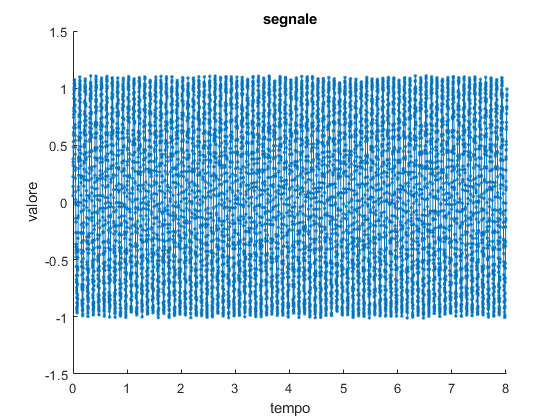

dt = 0.001;
xx = 0:dt:8.02;

tmp = xx;

if (0)
    for i = 2:numel(xx)
        xx(i) = xx(i-1) + dt + randn * dt * 0.01;
    end
end

F = 10;
% yy = sin(xx * 10 * 2 * pi) + 0.1*square(xx * 10 * 2 * pi) + ...
%     rand(1, numel(xx))*0.1 + 1;
% yy = sawtooth(xx * 10 * 2 * pi, 0.5) + rand(1, numel(xx))*0.1 + 1;
yy = sin(xx * F * 2 * pi) + cos(xx * F * 2 * pi * 3) * 0.05 +...
    0.1*rand(1, numel(xx));
xx = tmp;

figure;
hold on;
plot(xx, yy, '.-')
title("segnale");
xlabel("tempo");
ylabel("valore");
xlim([0, max(xx)]);
hold off;

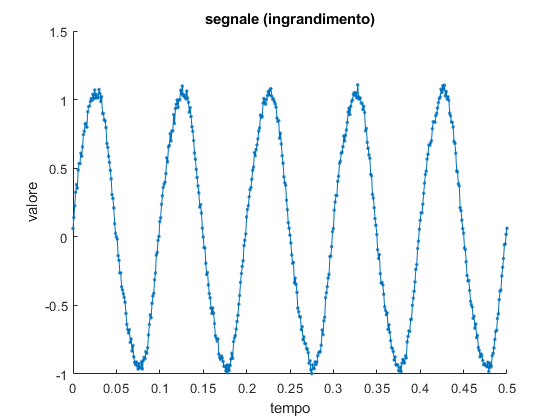


figure;
hold on;
plot(xx, yy, '.-')
title("segnale (ingrandimento)");
xlabel("tempo");
ylabel("valore");
xlim([0, 0.5]);
hold off;

### trasformata

[freqs, A, phi] = myFFT(yy, dt);

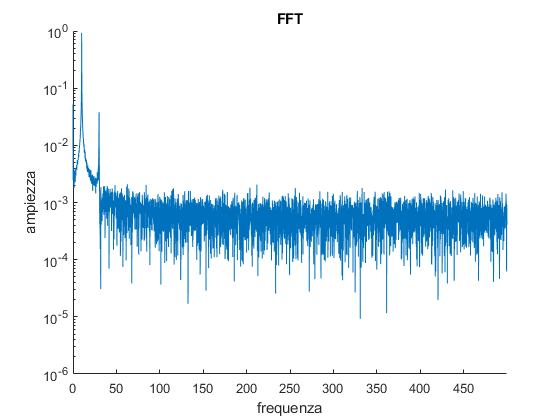


figure;
hold on;
title("FFT");
plot(freqs(1:end), A)
set(gca, "YScale", "log");
xlabel("frequenza");
ylabel("ampiezza");
xlim([min(freqs), max(freqs)]);
hold off;

#### Ingrandimento

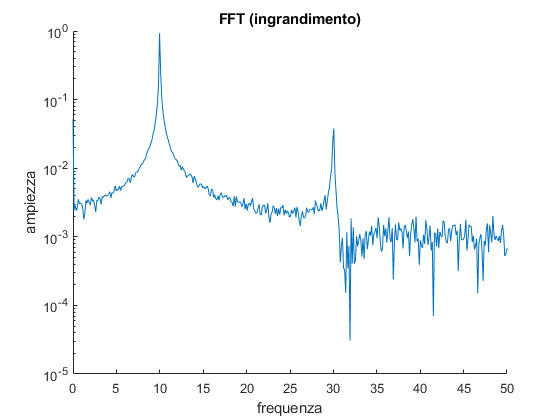

figure;
hold on;
title("FFT (ingrandimento)");
plot(freqs(1:end), A(1:end))
set(gca, "YScale", "log");
xlabel("frequenza");
ylabel("ampiezza");
xlim([0, 50]);
hold off;

## Processing

### ricerca frequenza principale

ignoriamo l'incertezza

[mainFreq, dmainFreq] = calcolaFmax(yy - mean(yy), dt);
fprintf("frequenza principale: %f +- %f", mainFreq, dmainFreq);

frequenza principale: 9.999910 +- 0.000086

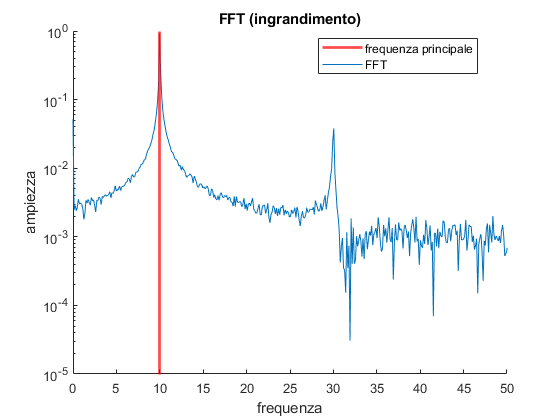


figure;
hold on;
xline(mainFreq, 'r', "LineWidth", 2);
title("FFT (ingrandimento)");
plot(freqs(1:end), A(1:end))
set(gca, "YScale", "log");
xlabel("frequenza");
ylabel("ampiezza");
xlim([0, 50]);
hold off;
legend("frequenza principale", "FFT", "Location","best")

### Ridimensionamento acquisizione

numero di onde acquisite:

N_onde = floor(numel(yy) * dt * mainFreq)

N_onde = 80

N_punti = floor(min((N_onde / mainFreq) / dt, numel(yy)));

figure;
hold on
plot(xx, yy - mean(yy), '.k-')
title("segnale");
xlabel("tempo");
ylabel("valore");
currXlim = [0, max(xx)];
xlim(currXlim);
currYlim = ylim;

ridimensionamento:

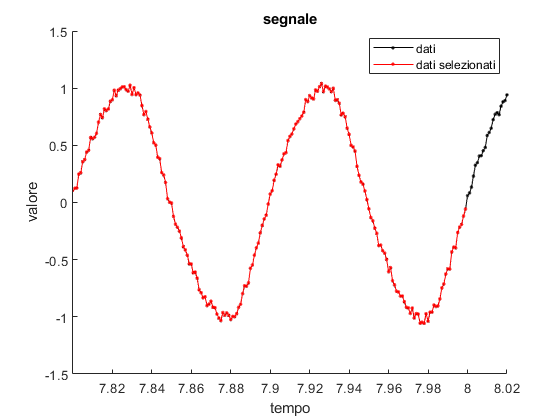

yy = yy(1:N_punti);
yy = yy - mean(yy);
xx = xx(1:N_punti);

currXlim(1) = (N_onde-2) / mainFreq;
plot(xx, yy, '.r-')
xlim(currXlim);
ylim(currYlim);
legend("dati", "dati selezionati", "Location","best");
hold off

ricalcolo FFT

[freqs, A, phi] = myFFT(yy, dt);

old_mainFreq = mainFreq;
old_dmainFreq = dmainFreq;
clear mainFreq dmainFreq;

[~, max_index] = max(A);
mainFreq = freqs(max_index)

mainFreq = 10

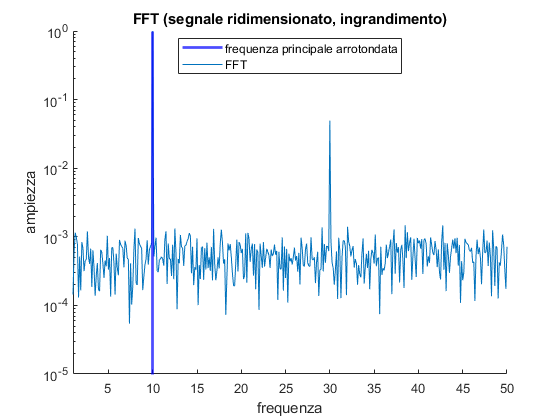


figure;
hold on;
xline(mainFreq, 'b', "LineWidth", 2);
title("FFT (segnale ridimensionato, ingrandimento)");
plot(freqs, A)
set(gca, "YScale", "log");
xlabel("frequenza");
ylabel("ampiezza");
xlim([1, 50]);
hold off;
legend("frequenza principale arrotondata", "FFT", "Location","best")

### Armoniche

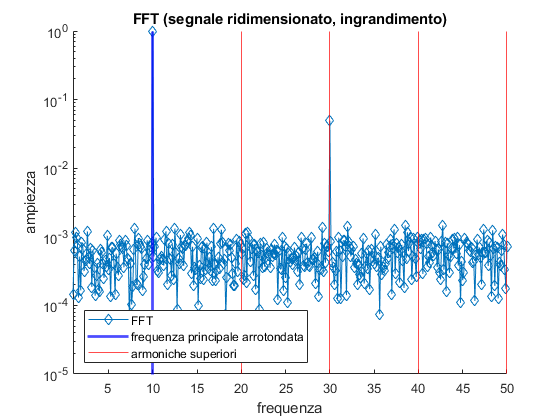

figure;
hold on;

title("FFT (segnale ridimensionato, ingrandimento)");
plot(freqs, A, 'd-', "Color", [0 0.4470 0.7410])
set(gca, "YScale", "log");
xlabel("frequenza");
ylabel("ampiezza");
xlim([1, 50]);
currXlim = xlim;
xline(mainFreq, 'b', "LineWidth", 2);
for i = 2:10
    xline(mainFreq * i, 'r');
end
hold off;
legend("FFT", "frequenza principale arrotondata", "armoniche superiori", ...
    "Location","southwest")

## Amplificazione delle non linearità:

signal_fft = fft(yy);

azzeriamo tutte la componenti non periodiche:

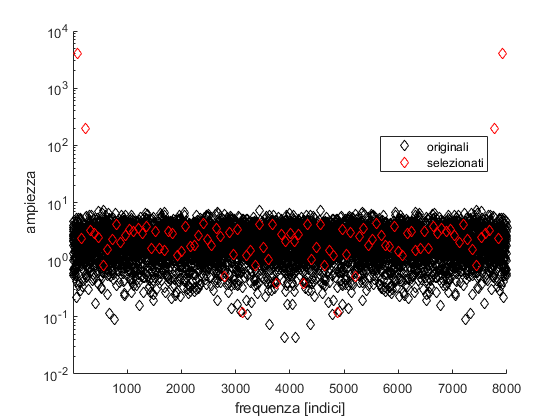

figure;
hold on;
plot(abs(signal_fft), 'kd');
for i = 1:ceil(numel(signal_fft)/2)
    if (mod(i-1, max_index-1) ~= 0)
        signal_fft(i) = 0;
        signal_fft(numel(signal_fft) - i + 2) = 0;
    end
end
plot(abs(signal_fft), 'rd');
set(gca, "YScale", 'log');
legend("originali", "selezionati", "Location","best");
xlabel("frequenza [indici]");
ylabel("ampiezza");
tmp = xlim;
tmp(1) = 2;
xlim(tmp);
hold off;

### Amplificazione non linearità:

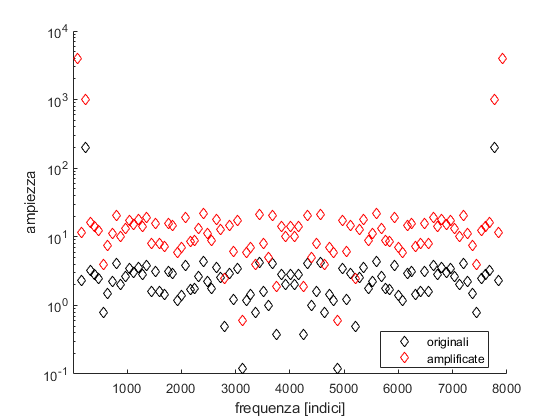

% fattore di amplificazione delle armoniche secondarie
amplificazione = 5;

% percentuale finale dell'armonica principale:
fattore_attenuazione = 1 / amplificazione;


figure;
hold on;
plot(abs(signal_fft), 'kd');

yy_smooth = ifft(signal_fft);

signal_fft(max_index) = signal_fft(max_index) * fattore_attenuazione;
signal_fft(numel(signal_fft) - max_index + 2) = ...
    signal_fft(numel(signal_fft) - max_index + 2) * fattore_attenuazione;
signal_fft = signal_fft * amplificazione;

plot(abs(signal_fft), 'rd');
set(gca, "YScale", 'log');
legend("originali", "amplificate", "Location","best");
xlabel("frequenza [indici]");
ylabel("ampiezza");
tmp = xlim;
tmp(1) = 2;
xlim(tmp);
hold off;


figure;
hold on;
title("amplificazione armoniche x" + num2str(amplificazione))
plot(xx, yy, '.k-')
plot(xx, yy_smooth, 'b-')
plot(xx, ifft(signal_fft), 'r-')
xlim([0, 1 / mainFreq * 3]);
xlabel("tempo");
ylabel("valore");
legend("segnale originale", "mediato", "mediato & armoniche x" + ...
    num2str(amplificazione), "Location","best")
hold off

ingrandimento

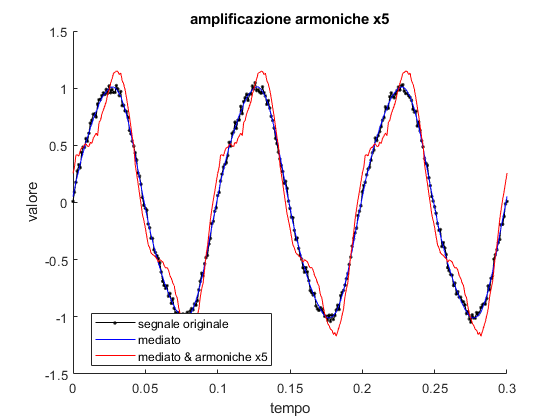

a1 = gca;
f2 = figure;
a2 = copyobj(a1,f2);

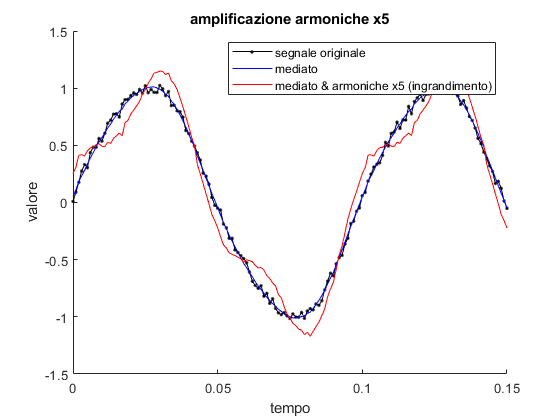

xlim([0, 1/mainFreq * 1.5]);
legend("segnale originale", "mediato", "mediato & armoniche x" + ...
    num2str(amplificazione) + " (ingrandimento)", "Location","northeast");

## Note

se l'errore in frequenza è troppo grande allora l'ampiezza trovata diminuisce. Considera qualcosa tipo una rinormalizzazione che considera le componenti non periodiche. tipo se si mette il rumore in tempo a > 0.1 allora l'ampiezza della media è più piccola